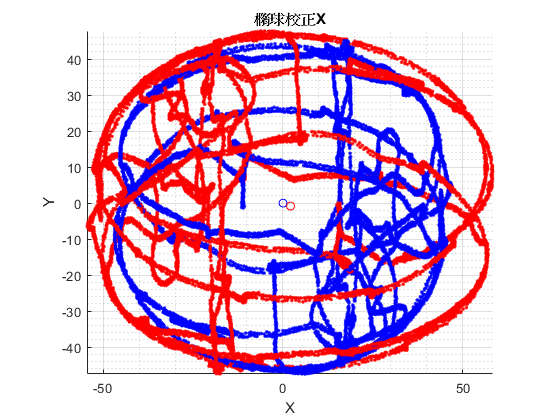

clear; close all;


% fitdata=xlsread('fit data\11 26 new fit data 2mag new place_th_2.8_m2濾y.xlsx');
fitdata=xlsread('fit data\data_corr_16475_5_25_IP.xlsx');
Ba=fitdata(1:3,1);Ta=fitdata(1:3,2:4);Ka=fitdata(1:3,5:7);
Bg=fitdata(5:7,1);Tg=fitdata(5:7,2:4);Kg=fitdata(5:7,5:7);
Bm=fitdata(9:11,1);Tm2a=fitdata(9:11,2:4);
Bm_2=fitdata(13:15,1);Tm2a_2=fitdata(13:15,2:4);

% 時間  加速度(m/s/s)XYZ 角速度XYZ 磁力XYZ 放在data.txt 中
% data=load('fitdata\11 26 new fit code 2mag new place grass.csv');
data=load('fit data\fitdata16475.csv');

acc=data(:,2:4);
gyr=data(:,5:7);
mag=data(:,8:10);
mag2=data(:,11:13);
Aa=sqrt(acc(:,1).^2+acc(:,2).^2+acc(:,3).^2);
Ag=sqrt(gyr(:,1).^2+gyr(:,2).^2+gyr(:,3).^2);
Am=sqrt(mag(:,1).^2+mag(:,2).^2+mag(:,3).^2);
Am2=sqrt(mag2(:,1).^2+mag2(:,2).^2+mag2(:,3).^2);


[a1 a2]=size(data);
data_corr=zeros(a1,a2);
data_corr(:,1)=data(:,1);
for i=1:a1   %校正數據
    data_corr(i,2:4)=(Ta*Ka*(data(i,2:4)'+Ba))';
    data_corr(i,5:7)=(Tg*Kg*(data(i,5:7)'+Bg))';
    data_corr(i,8:10)=(Tm2a*(data(i,8:10)'+Bm))';
    data_corr(i,11:13)=(Tm2a_2*(data(i,11:13)'+Bm_2))';
end
X=data(:,8:10);
Xnew=data_corr(:,8:10);
Xneww=sqrt(Xnew(:,1).^2+Xnew(:,2).^2+Xnew(:,3).^2);
Xw=sqrt(X(:,1).^2+X(:,2).^2+X(:,3).^2);
X2=data(:,11:13);
Xnew2=data_corr(:,11:13);
Xneww2=sqrt(Xnew2(:,1).^2+Xnew2(:,2).^2+Xnew2(:,3).^2);
Xw2=sqrt(X2(:,1).^2+X2(:,2).^2+X2(:,3).^2);

close all
figure(1)
hold on

scatter3(X(:,1),X(:,2),X(:,3),'red.')
scatter3(Xnew(:,1),Xnew(:,2),Xnew(:,3),'blue.')
scatter3(Bm(1)*-1,Bm(2)*-1,Bm(3)*-1,'ro')
scatter3(0,0,0,'blueo')

title('橢球校正X')
grid on
grid minor
axis equal tight
xlabel('X');
ylabel('Y');
zlabel('Z');
hold off

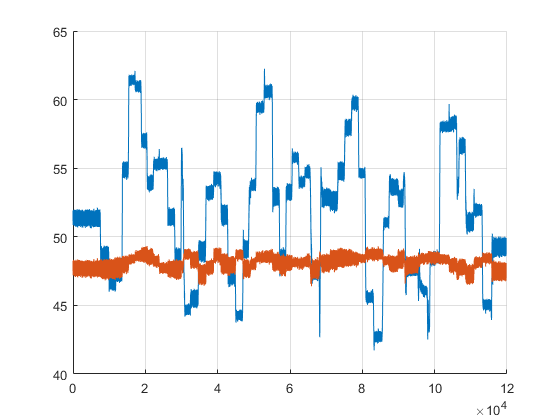

%
figure(2)
hold on
plot(Xw)
plot(Xneww)
grid on
hold off

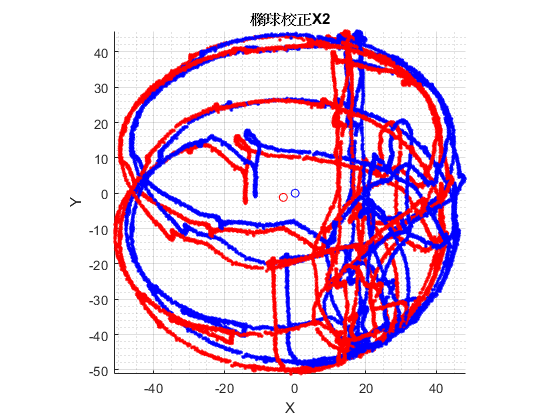


figure(3)
hold on
%
scatter3(X2(:,1),X2(:,2),X2(:,3),'red.')
scatter3(Xnew2(:,1),Xnew2(:,2),Xnew2(:,3),'blue.')
scatter3(Bm_2(1)*-1,Bm_2(2)*-1,Bm_2(3)*-1,'ro')
scatter3(0,0,0,'blueo')
%
title('橢球校正X2')
grid on
grid minor
axis equal tight
xlabel('X');
ylabel('Y');
zlabel('Z');
hold off

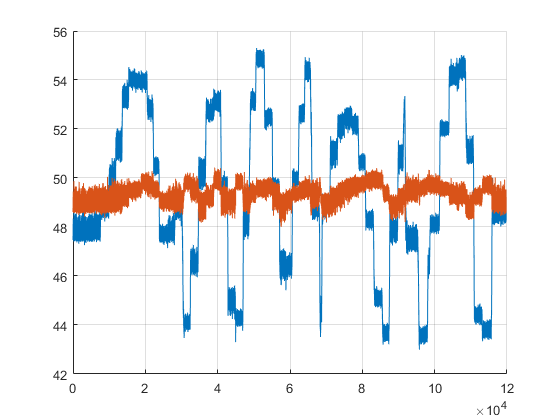

%
figure(4)
hold on
plot(Xw2)
plot(Xneww2)
grid on
hold off

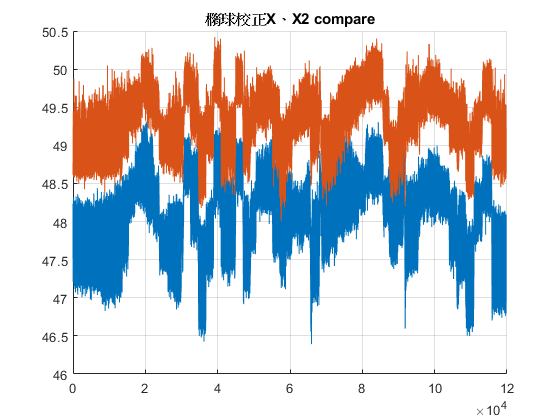


figure(5)
hold on
plot(Xneww)
plot(Xneww2)
grid on
title('橢球校正X、X2 compare')
hold off

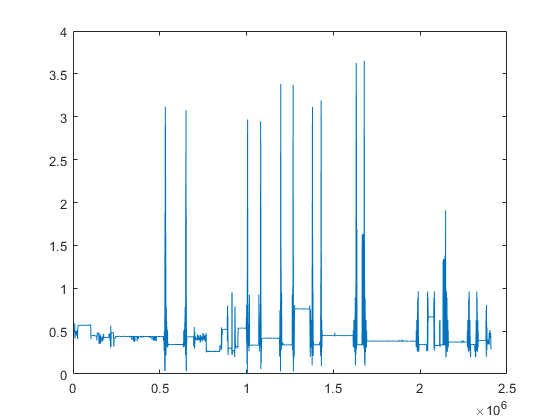

%% Corr_Mag
clear all;close all;
% fitdata=xlsread('fit data\11 26 new fit data 2mag new place_th_2.8_m2濾y.xlsx');
fitdata=xlsread('fit data\data_corr_16475_5_25_IP.xlsx');

Ba=fitdata(1:3,1);Ta=fitdata(1:3,2:4);Ka=fitdata(1:3,5:7);
Bg=fitdata(5:7,1);Tg=fitdata(5:7,2:4);Kg=fitdata(5:7,5:7);
Bm=fitdata(9:11,1);Tm2a=fitdata(9:11,2:4);
Bm_2=fitdata(13:15,1);Tm2a_2=fitdata(13:15,2:4);

close all

mo1=load('proj\11 8 undergroundpipe pull and ladder\LOG195.csv');
mo2=load('proj\11 8 undergroundpipe pull and ladder\LOG196.csv');
% mo3=load('proj\11 8 undergroundpipe pull and ladder\LOG197.csv');

%  moo=mo;

moo=[mo1;mo2];   %5 25

[No,~]=size(moo);
t0=[1 No];
t=moo(:,1);

% mo=moo(:,[1:4,8:16]);
mo=moo(:,[1:13]);  %%%%%%%%%%%%%%%%16475%%%%%%%%%%%%%%%%%%
[a1 a3]=size(moo);
[a1 a2]=size(mo);
f=moo(:,a3); %freqency
mo_cor=zeros(a1,a2);
% mo_cor=mo;

% mo_cor(:,1)=mo(:,1);
% for i=1:a1   %校正數據
%     mo_cor(i,2:4)=(Ta*Ka*(mo(i,2:4)'+Ba))';
%     mo_cor(i,5:7)=(Tg*Kg*(mo(i,5:7)'+Bg))';
%     mo_cor(i,8:10)=(Tm2a*(mo(i,8:10)'+Bm))';
%     mo_cor(i,11:13)=(Tm2a_2*(mo(i,11:13)'+Bm_2))';
% end

% acc1 = mo_cor(:,2:4);  %有校正
% gyr=mo_cor(:,5:7);
% % acc2 = mo_cor(:,5:7);
% m = mo_cor(:,8:10)*0.01;   %%%% to guess
% m2 = mo_cor(:,11:13)*0.01;   %%%%

acc1 = mo(:,2:4);  %無校正
gyr=mo(:,5:7);
m = mo(:,8:10)*0.01; %%%% to guess
m2 = mo(:,11:13)*0.01; %%%%

ax=acc1(:,1);ay=acc1(:,2);az=acc1(:,3);
% ax2=acc2(:,1);ay2=acc2(:,2);az2=acc2(:,3);
aGo=sqrt(mo_cor(:,2).^2+mo_cor(:,3).^2+mo_cor(:,4).^2);
% aG2o=sqrt(mo_cor(:,5).^2+mo_cor(:,6).^2+mo_cor(:,7).^2);
aG=sqrt(ax.^2+ay.^2+az.^2);
% aG2=sqrt(ax2.^2+ay2.^2+az2.^2);

GG=sqrt(gyr(:,1).^2+gyr(:,2).^2+gyr(:,3).^2)*0.01;

mm4=sqrt(m(:,1).^2+m(:,2).^2+m(:,3).^2);
mm42=sqrt(m2(:,1).^2+m2(:,2).^2+m2(:,3).^2);

stdd=std(mo)'; %看標準差
stdd_cor=std(mo_cor)';

plot(mm42)

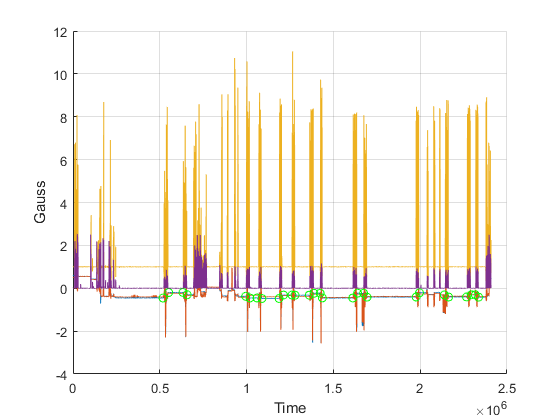

%% 定位AGM資料點
hour1=0; mins1=30; secs1=2; %5 26 IP 時間點
hour=[0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 1 1 1 1 1 1 1 1 1 1];
mins=[-5 -4 0 1 17 18 20 21 26 27 30 30 34 36 37 38 46 48 49 50 4 5 12 13 18 19 20 21];
secs=[-35 0 -5 5 13 25 20 42 27 40 0 52 48 7 50 26 53 12 52 47 13 10 0 10 4 22 30 23];


[~,k]=size(mins);
on=[];
for i=1:k
    on(i)=hour(i)*60*60+mins(i)*60+secs(i);
end
on1=hour1*60*60+mins1*60+secs1;

% on=on-on1+t(642817);
% on=on-on1+t(528075);
on=on+on1;

[~,k]=size(on);
ed=[];
eds=[];
ton=[];
toff=[];
ed(k,:)=0;
eds(k,3)=0;
ton(k,:)=0;
toff(k,:)=0;

for i=1:k
    [~,ton(i)]=min(abs(t-on(i)));
end
ticks=[ton];
ticks=reshape (ticks, 1, numel(ticks));
ticks=sort(ticks,'ascend');


close all
hold on
plot(m(:,1))
plot(m2(:,1)*-1)
tickson=[ton];
tickson=reshape (tickson, 1, numel(tickson));
tickson=sort(tickson,'ascend');

for i=1:k
    plot(tickson(i),m(tickson(i),1),'go')
end
plot(aG)
plot(GG)
% set(gca, 'xtick', ticks);
grid on
xlabel('Time')
ylabel('Gauss')
hold off

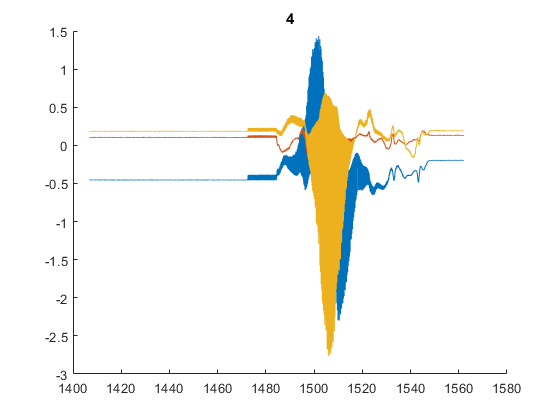

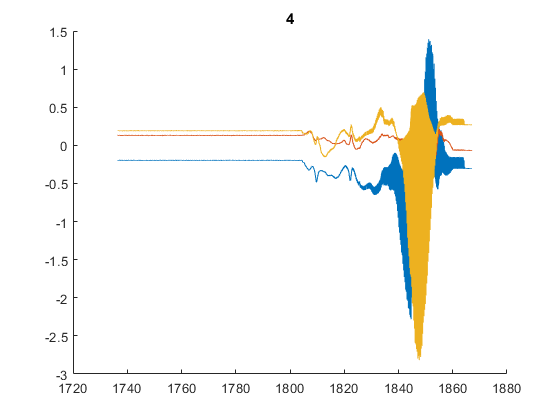

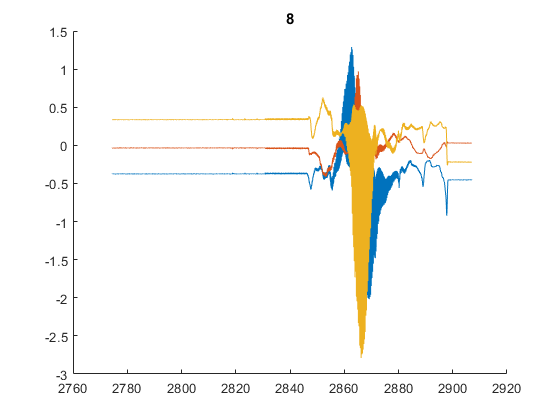

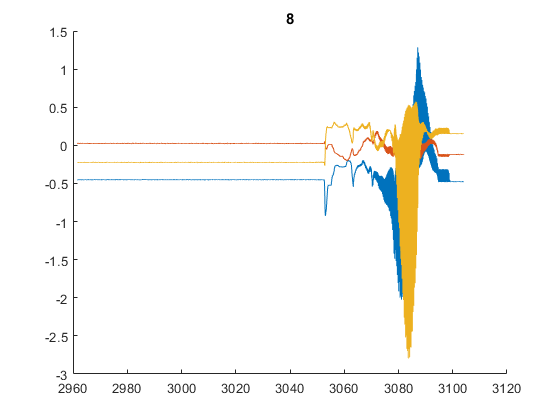

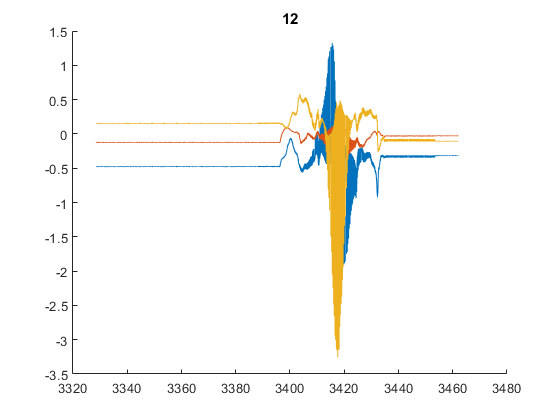

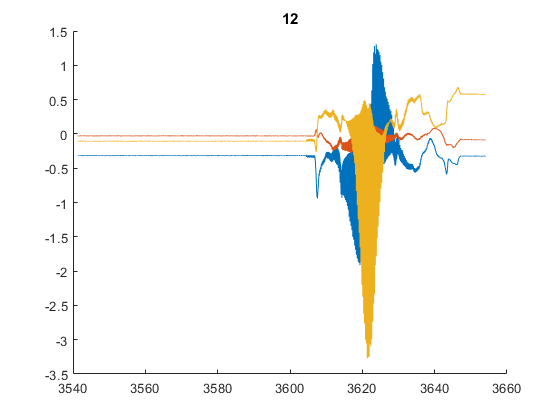

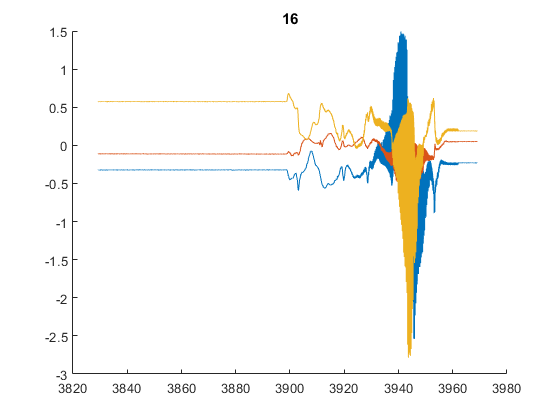

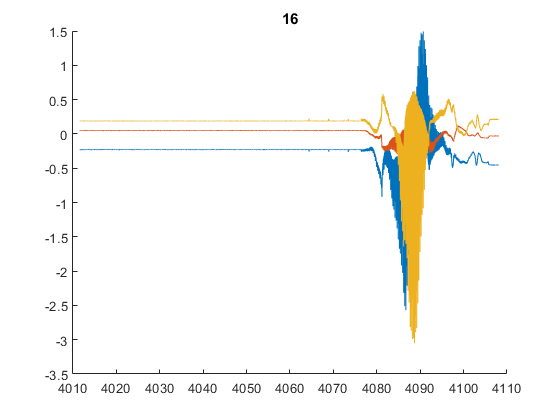

%% 取出AGM磁力區間
l=k/2;
close all;
agm=[4 4 8 8 12 12 16 16 20 20 24 24 28 28];
axi=1;
for i=1:l
    figure(i)
    title(agm(i))
    nn=ton(1+(i-1)*2)-350*60:ton(2+(i-1)*2);
    hold on
    plot(t(nn),m(nn,1))
    plot(t(nn),m(nn,2))
    plot(t(nn),m(nn,3))
end

%% data output
for i=1:l
    nn=ton(1+(i-1)*2)-350*60:ton(2+(i-1)*2);
    delemagn=[num2str(agm(i)) '-' num2str(mod(i,2))];
    delemagdata=[t(nn,:) acc1(nn,:) gyr(nn,:) m(nn,:) m2(nn,:)];
    text={'time' 'a1x' 'a1y' 'a1z' 'gx' 'gy' 'gz' 'm1x' 'm1y' 'm1z' 'm2x' 'm2y' 'm2z'};
    xlswrite('proj\11 8 undergroundpipe pull and ladder\11 8 undergroundpipe1.xlsx',text,delemagn)
    xlswrite('proj\11 8 undergroundpipe pull and ladder\11 8 undergroundpipe1.xlsx',delemagdata,delemagn,'A2')
end

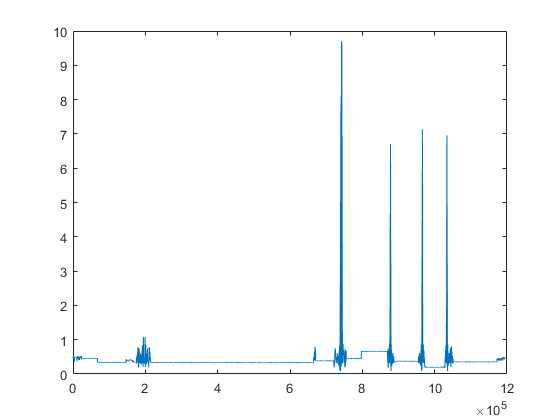

%% Corr_Mag
clear all;close all;
% fitdata=xlsread('fit data\11 26 new fit data 2mag new place_th_2.8_m2濾y.xlsx');
fitdata=xlsread('fit data\data_corr_16475_5_25_IP.xlsx');

Ba=fitdata(1:3,1);Ta=fitdata(1:3,2:4);Ka=fitdata(1:3,5:7);
Bg=fitdata(5:7,1);Tg=fitdata(5:7,2:4);Kg=fitdata(5:7,5:7);
Bm=fitdata(9:11,1);Tm2a=fitdata(9:11,2:4);
Bm_2=fitdata(13:15,1);Tm2a_2=fitdata(13:15,2:4);

close all

% mo1=load('proj\11 8 undergroundpipe pull and ladder\LOG195.csv');
% mo2=load('proj\11 8 undergroundpipe pull and ladder\LOG196.csv');
mo3=load('proj\11 8 undergroundpipe pull and ladder\LOG197.csv');

%  moo=mo;

moo=[mo3];   %5 25

[No,~]=size(moo);
t0=[1 No];
t=moo(:,1);

% mo=moo(:,[1:4,8:16]);
mo=moo(:,[1:13]);  %%%%%%%%%%%%%%%%16475%%%%%%%%%%%%%%%%%%
[a1 a3]=size(moo);
[a1 a2]=size(mo);
f=moo(:,a3); %freqency
mo_cor=zeros(a1,a2);
% mo_cor=mo;

% mo_cor(:,1)=mo(:,1);
% for i=1:a1   %校正數據
%     mo_cor(i,2:4)=(Ta*Ka*(mo(i,2:4)'+Ba))';
%     mo_cor(i,5:7)=(Tg*Kg*(mo(i,5:7)'+Bg))';
%     mo_cor(i,8:10)=(Tm2a*(mo(i,8:10)'+Bm))';
%     mo_cor(i,11:13)=(Tm2a_2*(mo(i,11:13)'+Bm_2))';
% end

% acc1 = mo_cor(:,2:4);  %有校正
% gyr=mo_cor(:,5:7);
% % acc2 = mo_cor(:,5:7);
% m = mo_cor(:,8:10)*0.01;   %%%% to guess
% m2 = mo_cor(:,11:13)*0.01;   %%%%

acc1 = mo(:,2:4);  %無校正
gyr=mo(:,5:7);
m = mo(:,8:10)*0.01; %%%% to guess
m2 = mo(:,11:13)*0.01; %%%%

ax=acc1(:,1);ay=acc1(:,2);az=acc1(:,3);
% ax2=acc2(:,1);ay2=acc2(:,2);az2=acc2(:,3);
aGo=sqrt(mo_cor(:,2).^2+mo_cor(:,3).^2+mo_cor(:,4).^2);
% aG2o=sqrt(mo_cor(:,5).^2+mo_cor(:,6).^2+mo_cor(:,7).^2);
aG=sqrt(ax.^2+ay.^2+az.^2);
% aG2=sqrt(ax2.^2+ay2.^2+az2.^2);

GG=sqrt(gyr(:,1).^2+gyr(:,2).^2+gyr(:,3).^2)*0.01;

mm4=sqrt(m(:,1).^2+m(:,2).^2+m(:,3).^2);
mm42=sqrt(m2(:,1).^2+m2(:,2).^2+m2(:,3).^2);

stdd=std(mo)'; %看標準差
stdd_cor=std(mo_cor)';

plot(mm42)

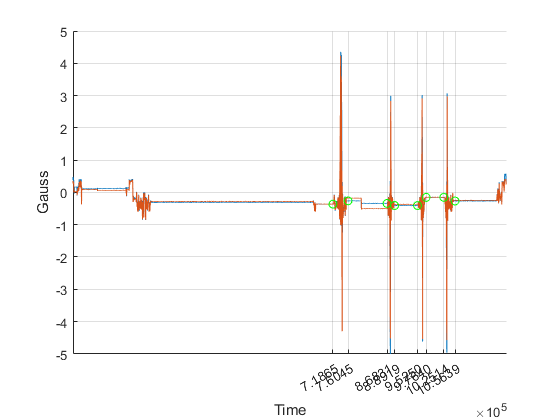

%% 定位AGM資料點
hour1=0; mins1=34; secs1=2; %5 26 IP 時間點
hour=[0 0 0 0 0 0 0 0];
mins=[0 2 7 8 11 12 14 16];
secs=[0 0 10 10 11 20 40 10];


[~,k]=size(mins);
on=[];
for i=1:k
    on(i)=hour(i)*60*60+mins(i)*60+secs(i);
end
on1=hour1*60*60+mins1*60+secs1;

on=on+on1;

[~,k]=size(on);
ed=[];
eds=[];
ton=[];
toff=[];
ed(k,:)=0;
eds(k,3)=0;
ton(k,:)=0;
toff(k,:)=0;

for i=1:k
    [~,ton(i)]=min(abs(t-on(i)));
end
ticks=[ton];
ticks=reshape (ticks, 1, numel(ticks));
ticks=sort(ticks,'ascend');


close all
hold on
plot(m(:,1))
plot(m2(:,1)*-1)
tickson=[ton];
tickson=reshape (tickson, 1, numel(tickson));
tickson=sort(tickson,'ascend');

for i=1:k
    plot(tickson(i),m(tickson(i),1),'go')
end
set(gca, 'xtick', ticks);
grid on
xlabel('Time')
ylabel('Gauss')
hold off

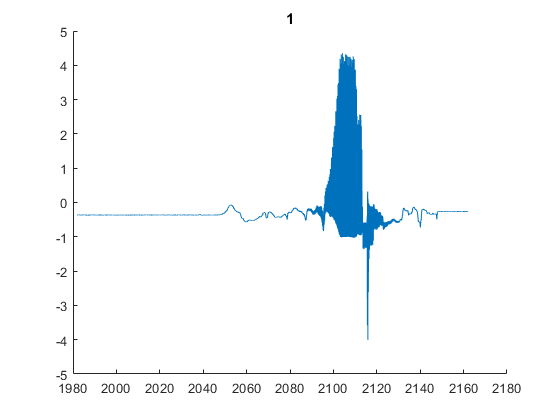

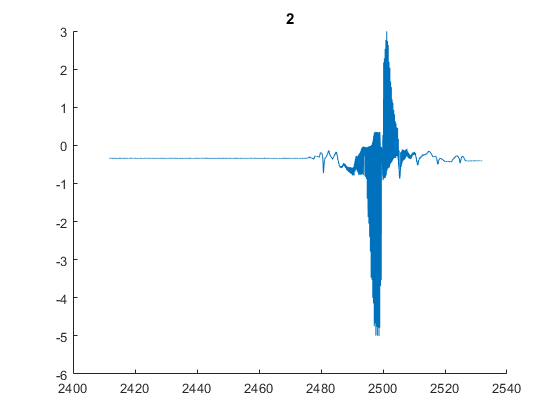

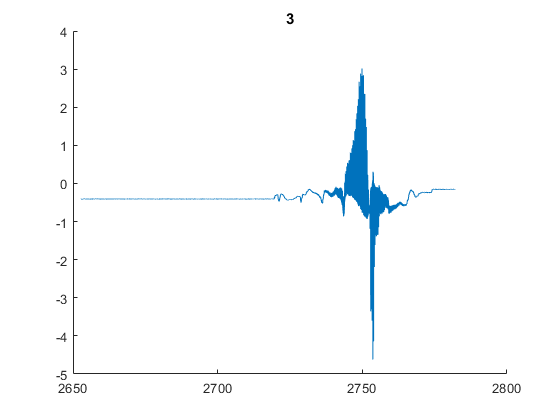

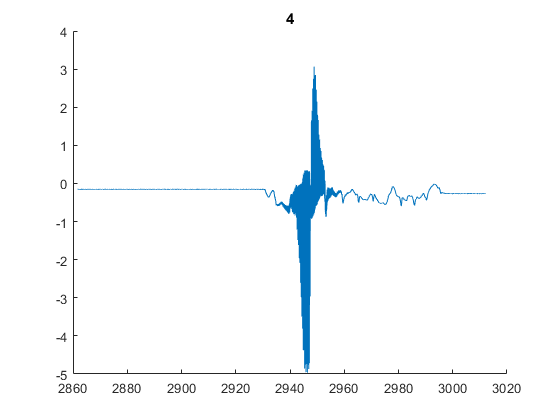

%% 取出AGM磁力區間
l=k/2;
close all;
agm=[1 2 3 4];
axi=1;
for i=1:l
    figure(i)
    title(agm(i))
    hold on
    nn=ton(1+(i-1)*2)-350*60:ton(2+(i-1)*2);
    plot(t(nn),m(nn))
end

%% data output
for i=1:l
    nn=ton(1+(i-1)*2)-350*60:ton(2+(i-1)*2);
    delemagn=[num2str(agm(i)) '-' num2str(mod(i,2)) '架高'];
    delemagdata=[t(nn,:) acc1(nn,:) gyr(nn,:) m(nn,:) m2(nn,:)];
    text={'time' 'a1x' 'a1y' 'a1z' 'gx' 'gy' 'gz' 'm1x' 'm1y' 'm1z' 'm2x' 'm2y' 'm2z'};
    xlswrite('proj\11 8 undergroundpipe pull and ladder\11 8 undergroundpipe2.xlsx',text,delemagn)
    xlswrite('proj\11 8 undergroundpipe pull and ladder\11 8 undergroundpipe2.xlsx',delemagdata,delemagn,'A2')
end